% This script file creates a plot for the part-01 of the experiment - 01

% Date: August 05, 2019
% Dr. Vibhav Durgesh
% Rev - 0.0
% Rev - 1.0 Modify for FA-2020
%----END-----------------------------

clear all
close all
clc

## Provide filename with directory

fid = fopen('../Data/myData.dat');
linel = fgetl(fid);

## Reading the data from the file and closing the file

data = fscanf(fid, '%f \n', [1 inf]);
x = data(1,:);
fclose(fid);

## Calculating the average and standard deviation

xavg = mean(x)

xavg = 3.6247

xstd = std(x)

xstd = 0.9888

## Generating figure with specific size

figure(1)
set(gcf,'unit','inches','position',[0.50 0.50, 6.50 3.50],...
        'defaultaxesfontsize',10,'defaultaxesfontname','times');

## Plotting data

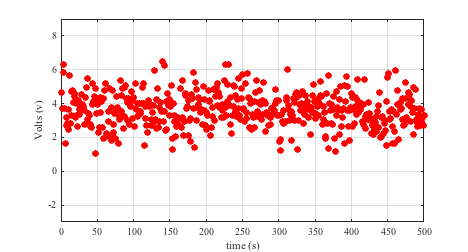

plot(x,'ro','markersize',6,'markerfacecolor','r'); hold on
xlabel('time (s)')
ylabel('Volts (v)')
grid on
ylim([-3 9])

## Setting legend and figure title

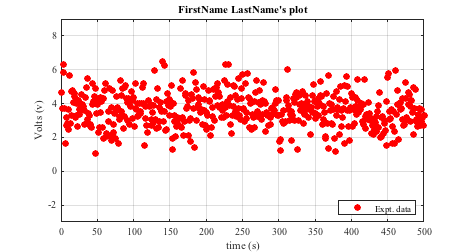

legend('Expt. data','location','SouthEast')
title('FirstName LastName''s plot')

## Saving figure files in png and pdf format

figName = ('../Figures/FirstName_LastName_ExptNo01_PartA1');
set(gcf,'PaperPositionMode','auto')
print(figName,'-dpng','-r600')
set(gcf,'Paperunits','inches','Units','inches');
figpos = get(gcf,'Position');
set(gcf,'Papersize',figpos(3:4),'Units','inches');
print(figName,'-dpdf','-r600')

## Generating second figure with specific size

figure(2)
set(gcf,'unit','inches','position',[0.50 0.50, 6.50 3.50],...
        'defaultaxesfontsize',10,'defaultaxesfontname','times');

## Plotting data using histogram command

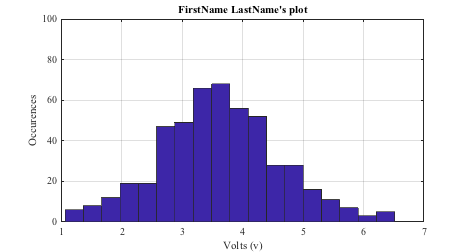

hist(x,18);
ylabel('Occurences')
xlabel('Volts (v)')
grid on
ylim([0 100])
title('FirstName LastName''s plot')

## Saving figure files in png and pdf format

figName = ('../Figures/FirstName_LastName_ExptNo01_PartA2');
set(gcf,'PaperPositionMode','auto')
print(figName,'-dpng','-r600')
set(gcf,'Paperunits','inches','Units','inches');
figpos = get(gcf,'Position');
set(gcf,'Papersize',figpos(3:4),'Units','inches');
print(figName,'-dpdf','-r600')